# Neural Network Notes and Algorithms

## Activation functions

Notes follow the [UFLDL Tutorial](http://ufldl.stanford.edu/tutorial/supervised/MultiLayerNeuralNetworks/) on Machine Learning at Stanford University

Activation functions are used to transition the input values into the subsequent neural network layers. A sigmoidal activation function, f(z), can be represented as


$$f\left(z\right)=\frac{1}{1+\mathrm{exp}\left(z\right)}$$


This function could be implemented in code as an anonymous function:

f_sig = @(z) (1+exp(-z)).^-1;

Alternative activation functions, such as the hyperbolic tangent functino, f(z) = tanh(z),


$$f\left(z\right)=\mathrm{tanh}\left(z\right)=\frac{e^z -e^{-z} }{e^z +e^{-z} }$$


f_tanh = @(z) tanh(z);

and the rectified linear function,

f_rect = @(z) max(0,z);

can also be used. 

Figure (1) plots the activation functions above.

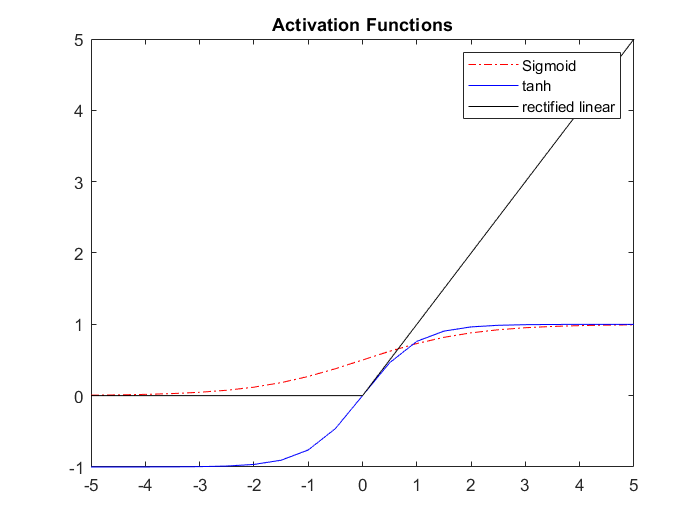

x = -5:0.5:5;
plot(x,f_sig(x),'r-.',x,f_tanh(x),'b',x,f_rect(x),'k')
legend('Sigmoid','tanh','rectified linear')
title('Activation Functions')

## Neural Network Structure

Suppose we have a neural network of three inputs (Layer L1), three hidden units (Layer L2) and an output layer comprising one unit (Layer L3). The below diagram shows such a network: 

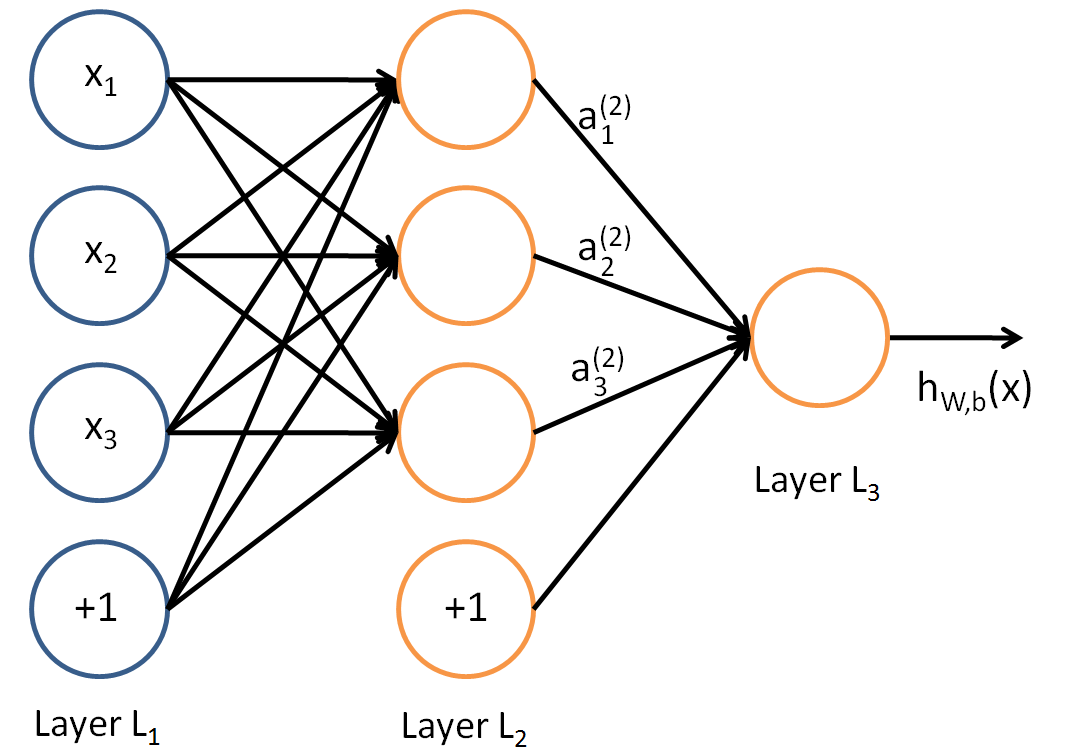

At each layer, the network applies the activation function *f(z)* to the input layer to acquire activation values $a_i^{\left(l\right)}$ for the subsequent layers. The forward propagation algorithm "propagates" the inputs into a "hypothesis", $h_{W,b} \left(x\right)=a^{\left(3\right)} =f\left(z^{l+1} \right)$, which is calculated by connecting each layer's operation with the subsequent layer through the activation function. As can be seen for this specific network, this means calculating 3 activation units for each input unit (plus a bias term), i.e. calculating *a1* values for each input. The term $z_i^{\left(l\right)}$ denotes the total weighted sum of all inputs of unit *i* in layer *l,* as well as the bias term.

Let us create an anonymous function in multiple terms to compute the activation values via forward propagation:

% Generic activation function a_i_l with inputs x = [2,1,4], 
% % bias terms b = [1,1,1] and weights 
% W1 = [1 1 1]
%      [1 1 1]
%      [1 1 1]
% W2 = [1 1 2]

x = [2 1 4];
W1 = [1 1 1;1 1 1;1 1 1];
W2 = [1 1 2];

bias = [1,1,1];
a_i_l = @(i,l, W) f_sig(W(i,l)+ W(i,l+1)+W(i,l+2) + bias(l,i))

for i = 1:3
    a1(i) = a_i_l(i,1,W1)
end

z1 = sum(a1)

